# **Simulate the MATLAB-based Ramsey-Cass-Koopmans Model using Parallel Computing**

This example shows how to simulate the MATLAB version of the Ramsey-Cass-Koopmans model using parallel computing constructs to speed up the simulation process.

*Copyright 2016-2023 The MathWorks, Inc.*

## Define the model parameters.

See [`defineRCKParams`](matlab: edit defineRCKParams) for more details.

defineRCKParams

## Create lattices of $(k, c)$ points for the simulation.

nPoints = 100;
k0Vec = linspace(0, 100, nPoints);
c0Vec = linspace(0, 3, nPoints);
[K0, C0] = meshgrid(k0Vec, c0Vec);

## Parametrize the coupled system of equations.

See [`RCK_Equations`](matlab: edit RCK_Equations) for more details.

RCK_Fun = @(t, Y) RCK_Equations(t, Y, params);

## Both per-capita wealth and consumption remain nonnegative over time.

We use [`odeset`](matlab: doc odeset) to define options for MATLAB's ODE solvers.

opts = odeset("NonNegative", [1, 2]);

## Create a time vector for the system.

In this example, time runs from $t_0=0$ to $t_{\text{end}}=1.5$.

t = linspace(0, 1.5, 1000);

## Perform the simulations in parallel.

parfor k = 1:numel(K0)

    % Initial values for per-capita wealth and consumption.
    Y0 = [K0(k); C0(k)];

    % Solve the coupled system. 
    % Suppress the integration warning.
    warningID = "MATLAB:ode45:IntegrationTolNotMet";
    warningStatus = warning("query", warningID);
    warning("off", warningID)
    [~, Y] = ode45(RCK_Fun, t, Y0, opts);
    k_out{k} = Y(:, 1); % Output per-capita wealth
    c_out{k} = Y(:, 2); % Output per-capita consumption    
    warning(warningStatus)
    
end % parfor

## Plot the results.

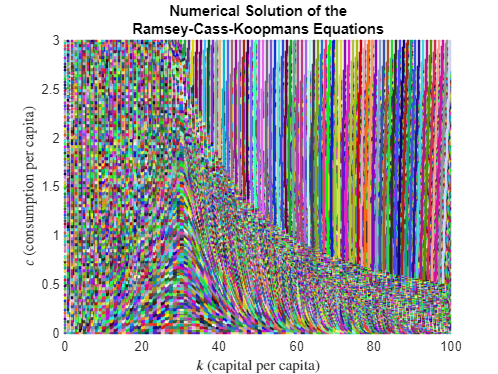

figure
hold on
for k = 1:numel(K0)
    plot(k_out{k}, c_out{k}, ".", "Color", rand(1, 3))
end
ylim([0, 3])
xlabel("$k$ (capital per capita)", "Interpreter", "latex")
ylabel("$c$ (consumption per capita)", "Interpreter", "latex")
title(sprintf("Numerical Solution of the\nRamsey-Cass-Koopmans Equations"))
grid on